## Sequential loops, for 8 dB linear doppler, 1e6 bits

Variación del doppler de -207 Hz/s con doppler inicial de 10e3 Hz



 ===== CONDITIONS ======
Eb/N0: 7.99 dB
Es/N0: 11.00 dB
Number of transmitted bits = 1000000
Number of transmitted symbols = 500000
Carrier frequency [MHz] = 450.00
Rb = 1000000
Rs = 500000

 ===== RESULTS ======
SER = 7.560000e-04
BER = 7.520000e-04



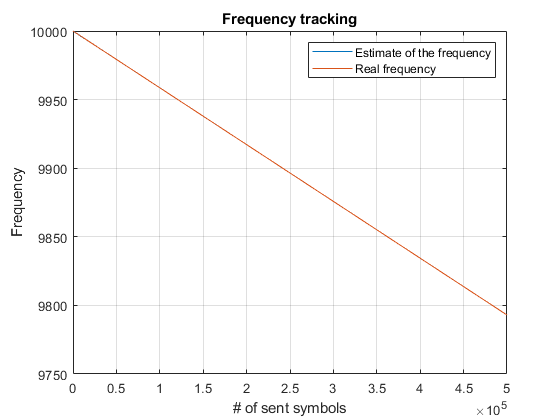

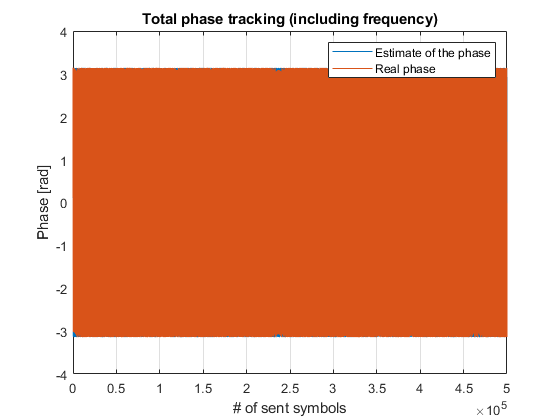

clear all;
close all;
load('simulation-05-Mar-2021_01_33_20.mat');
plot_results

## Sequential loops, for 0 dB linear doppler, 1e6 bits

Variación del doppler de -207 Hz/s con doppler inicial de 10e3 Hz



 ===== CONDITIONS ======
Eb/N0: 0.00 dB
Es/N0: 3.01 dB
Number of transmitted bits = 1000000
Number of transmitted symbols = 500000
Carrier frequency [MHz] = 450.00
Rb = 1000000
Rs = 500000

 ===== RESULTS ======
SER = 7.207080e-01
BER = 1.600310e-01



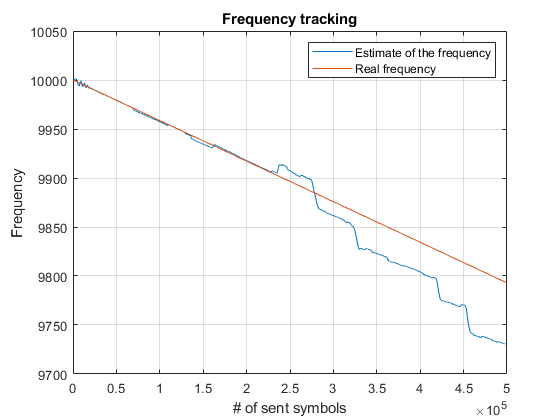

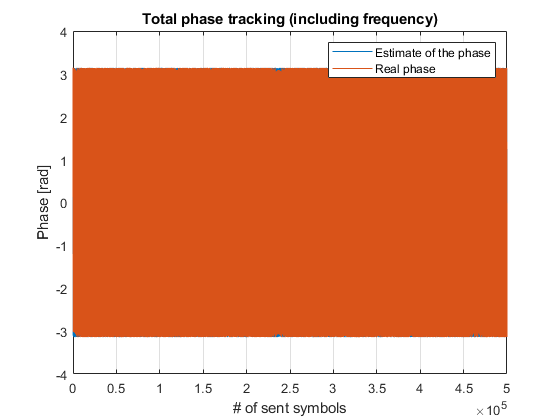

clear all;
close all;
load('simulation-05-Mar-2021_01_57_16.mat');
plot_results

## Sequential loops, for 8 dB linear doppler, 1e5 bits

Variación del doppler de -10e3 Hz/s con doppler inicial de 20e3 Hz



 ===== CONDITIONS ======
Eb/N0: 7.99 dB
Es/N0: 11.00 dB
Number of transmitted bits = 100000
Number of transmitted symbols = 50000
Carrier frequency [MHz] = 450.00
Rb = 1000000
Rs = 500000

 ===== RESULTS ======
SER = 7.200000e-04
BER = 7.200000e-04



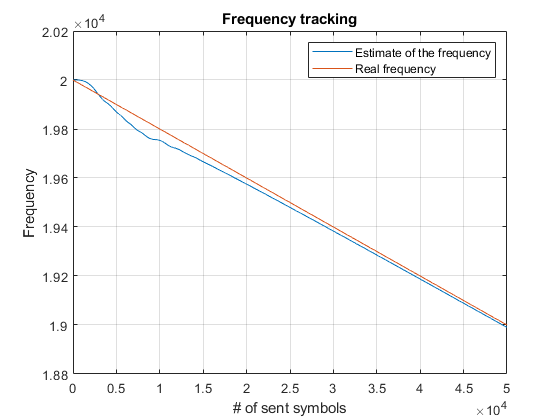

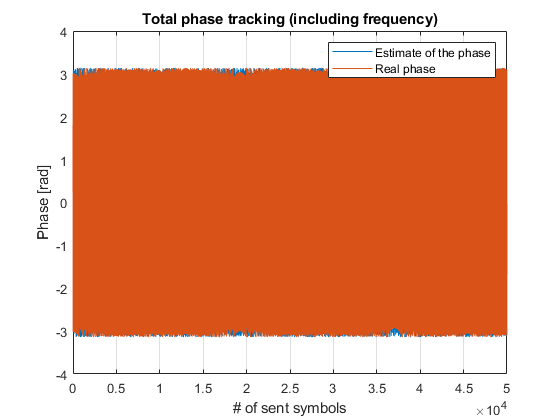

clear all;
close all;
load('simulation-12-Mar-2021_11_59_46.mat');
plot_results

## Sequential loops, for 8 dB linear doppler, 1e5 bits

Variación del doppler de -10e3 Hz/s con doppler inicial de 20e3 Hz



 ===== CONDITIONS ======
Eb/N0: 7.99 dB
Es/N0: 11.00 dB
Number of transmitted bits = 100000
Number of transmitted symbols = 50000
Carrier frequency [MHz] = 450.00
Rb = 1000000
Rs = 500000

 ===== RESULTS ======
SER = 7.200000e-04
BER = 7.200000e-04



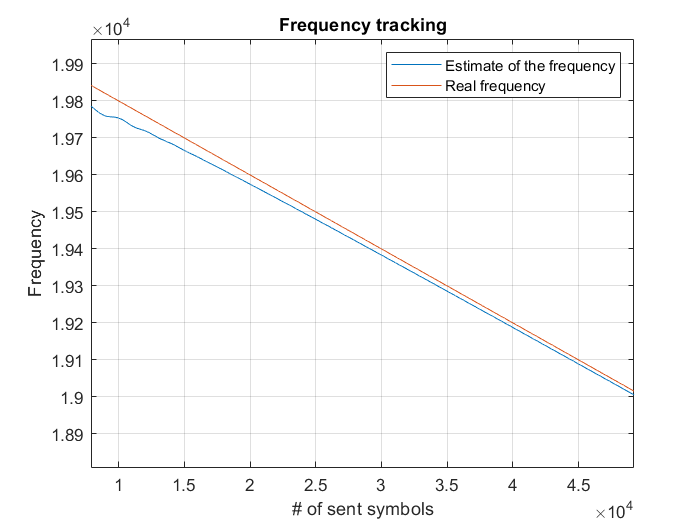

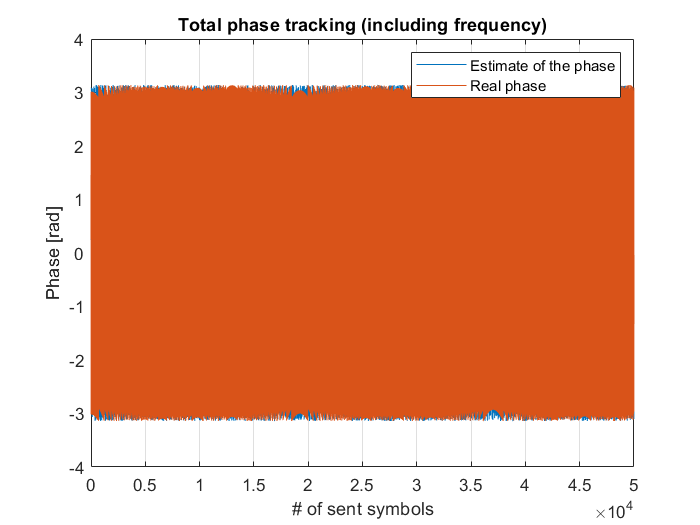

clear all;
close all;
load('simulation-12-Mar-2021_11_59_46.mat');
plot_results

## Sequential loops, for 8 dB real doppler, 1e6 bits

Variación del doppler de -10e3 Hz/s con doppler inicial de 20e3 Hz

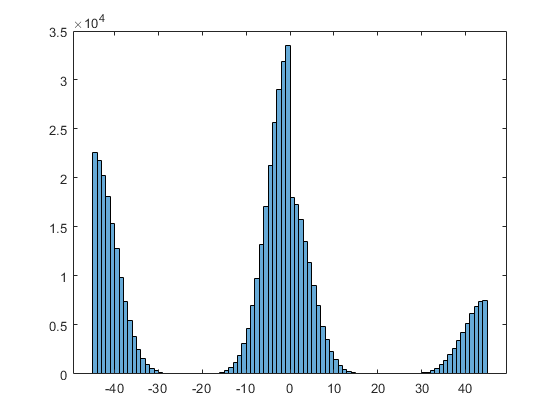



 ===== CONDITIONS ======
Eb/N0: 7.99 dB
Es/N0: 11.00 dB
Number of transmitted bits = 1000000
Number of transmitted symbols = 500000
Carrier frequency [MHz] = 450.00
Rb = 1000000
Rs = 500000

 ===== RESULTS ======
SER = 7.490660e-01
BER = 7.650000e-04



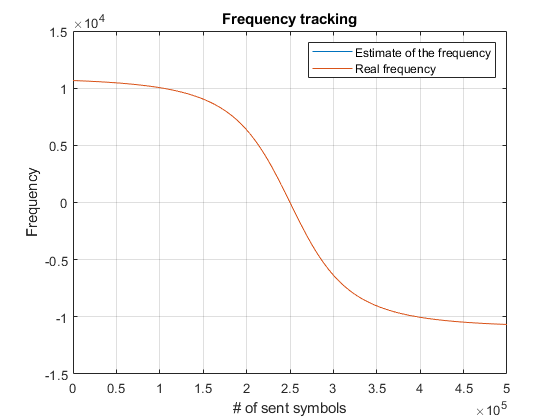

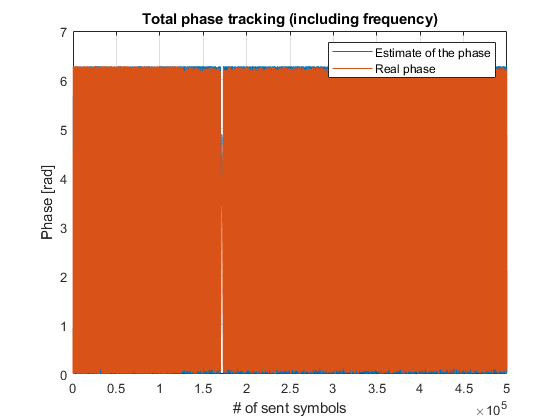

clear all;
close all;
load('simulation-12-Mar-2021_12_50_43.mat');
plot_results 

## Algunas conclusiones

Aquí estamos estudiando el tracking:

- La adquisición inicial no es tan importante porque no es un problema nuevo. Es estimar una portadora sin modular. Se diseñará pero no es tan complejo (no hay que extraer la portadora de la señal, la tenemos directamente).

- En el caso de que se pierda la sincronización totalmente, el estandar obliga a volver a mandar la portadora sin modular o sea que no se estudiará como este algoritmo hace la adquisición completa. Sí que se puede estudiar, cómo se comporta frente a fadings grandes o perdidas de señal de corta duración (si no, da igual que perdamos el enganche o no, porque los datos se perderán)

Como recordatorio de cómo funciona este algoritmo:

- FLL de segundo orden que sigue la frecuencia siendo capaz, sin contar el ruido, de seguir variaciones lineales de la frecuencia sin dejar ningún tipo de frecuencia residual. Podríamos hacerlo de primer orden y, sabiendo que va a haber un error residual, incluso si no hay ruido, dejar que el PLL compense ese error. Los terminos cuadráticos, cúbicos etc, del doppler (que los tiene), se están ignorando porque son despreciables y más a largo plazo. El termino lineal es más evidente, sobre todo cuando el satélite se acerca al ángulo máximo de elevación de la órbita.

- El PLL de segundo orden elimina errores residuales en la frecuencia y estima la fase. Tiene que ser sin duda de segundo orden, porque si no, 

Se han elegido algoritmos basados en arquitecturas feedback porque los basados en arquitecturas feedforward son más orientados a datos mandados en bursts. En nuestro caso, queremos transmisión continua, incluso cuando no hay tramas y solo está la idle sequence. 

Una vez sabemos esto, sabemos que la clave del diseño de estos algoritmos se basa en:

- Diseño del detector (ya sea de frecuencia o de fase)

- Diseño del filtro que depende de cómo sea la salida del detector y de cómo sean las variaciones que tengamos. Este diseño del filtro, es, de alguna forma equivalente al diseño de la step size en la forma recursiva de los estimadores. De hecho (estos algoritmos se pueden ver como PLL/FLLs o como estimadores recursivos con con step sizes variables).

El seguimiento que hace del doppler es bueno. El error de la frecuencia de la señal frente al oscilador local es de unas decimas de Hz aproximadamente. Por ahora no hay más métricas aparte del BER, el error absoluto medio y mirar la propia gráfica en puntos concretos. Se podría calcular el error cuadrático medip.

Un filtro de Kalman sustituyendo a los filtros LTI que hay ahora podría dar mayor robustez en entornos mucho más dinámicos, pero, ¿de verdad lo necesitamos?

Se ha simulado el doppler en un rango de 1 segundo, cuando realmente la variación va a ser a lo largo de 6 minutos. Queda probar un poco mejor cómo aguanta a largo plazo y cuales son las probabilidades de que pierda el enganche. Tambien se le pueden meter variaciones en la fase, un efecto de fading que haga que haya un SNR distinto para cada símbolo. Estamos asumiento que las variaciones de la fase son suficientemente lentas como para poder seguirlas. 

Se debe contemplar la posibilidad de hacerlo menos complejo, quizas hacer que el filtro del FLL sea de primer orden (y que el error residual lo conpense el PLL). Se puede intentar hacer construir una solución que minimice las operaciones haciendo las que tengan en común juntas (aun asi es dificil porque uno depende del otro).

Se debe estudiar un poco mejor analíticamente qué parámetros (gamma y ro) son óptimos para nuestro filtro, o por lo menos dar un visión de como afectan de verdad a distintos parámetros

Se debe estudiar cómo funciona el filtro para distintos SNRs.

Se debe estudiar el efecto de utilizar los datos al principio de la start sequence para mejorar la estimación. Sin embargo, no podemos garantizar cuánto tiempo va a pasar entre CLTU y CLTU, el canal podría estar un minuto entero en modo idle, y, como tenemos que diseñar para el peor caso, tenemos que asegurar que el algoritmo va  cumplir lo que queremos sin hacer uso de esta start sequence. La start sequence puede darnos aún mejor resultado. Para incluir la start sequence en el algorimto hay que mirar qué metodo es mejor de los propuestos en el Mengali: todos alcanza el limite modificado de Cramer-Rao y solo cambian en complejidad.

Se pueden probar otros algoritmos. Estas simulaciones se pueden reutilizar.